# Seuil corrélation

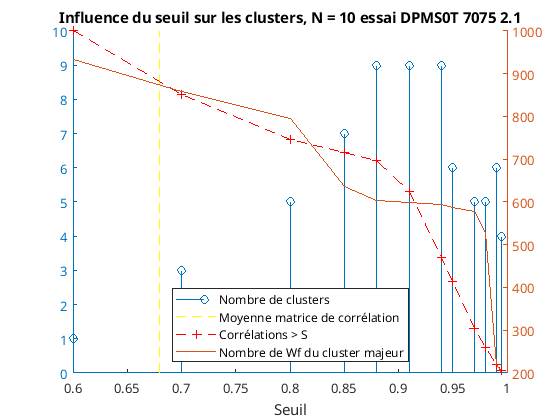

Seuil = [ 0.6 , 0.7, 0.8, 0.85, 0.88, 0.91, 0.94, 0.95, 0.97, 0.98, 0.99,0.995];
Nbre_corr =  [272271,221768,185984,175860,169090,144453,92314,72448,35682,20232,6413,1644];
Nbre_corr_norm = Nbre_corr*10/max(Nbre_corr);
Nbre_cluster = [1,3,5,7,9,9,9,6,5,5,6,4];
Nbre_WF_cluM = [933,858,796,636,603,599,594,587,577,526,221,202];

figure();
title("Influence du seuil sur les clusters, N = 10 essai DPMS0T 7075 2.1");
hold on
yyaxis left
stem(Seuil,Nbre_cluster);
plot([0.68,0.68],[0,10],'y--');
plot(Seuil,Nbre_corr_norm,"r+--");
yyaxis right
plot(Seuil,Nbre_WF_cluM);
hold off
legend({'Nombre de clusters', 'Moyenne matrice de corrélation','Corrélations > S','Nombre de Wf du cluster majeur'},"Location","south");
xlabel("Seuil");